%The script assumes zero actuator force and all inputs are road inputs
clc
clear
Pix_SS = get(0,'screensize')

Pix_SS =            1           1        1536         864


Actuator_Force = 0

N = 1.0e+09 *

    0.1842    3.0268


tf_road =
 
                      1.842e08 s + 3.027e09
  -------------------------------------------------------------
  20800 s^4 + 377300 s^3 + 6.636e07 s^2 + 1.842e08 s + 3.027e09
 
Continuous-time transfer function.



Choice_Road_Profile = 1

Control = 1

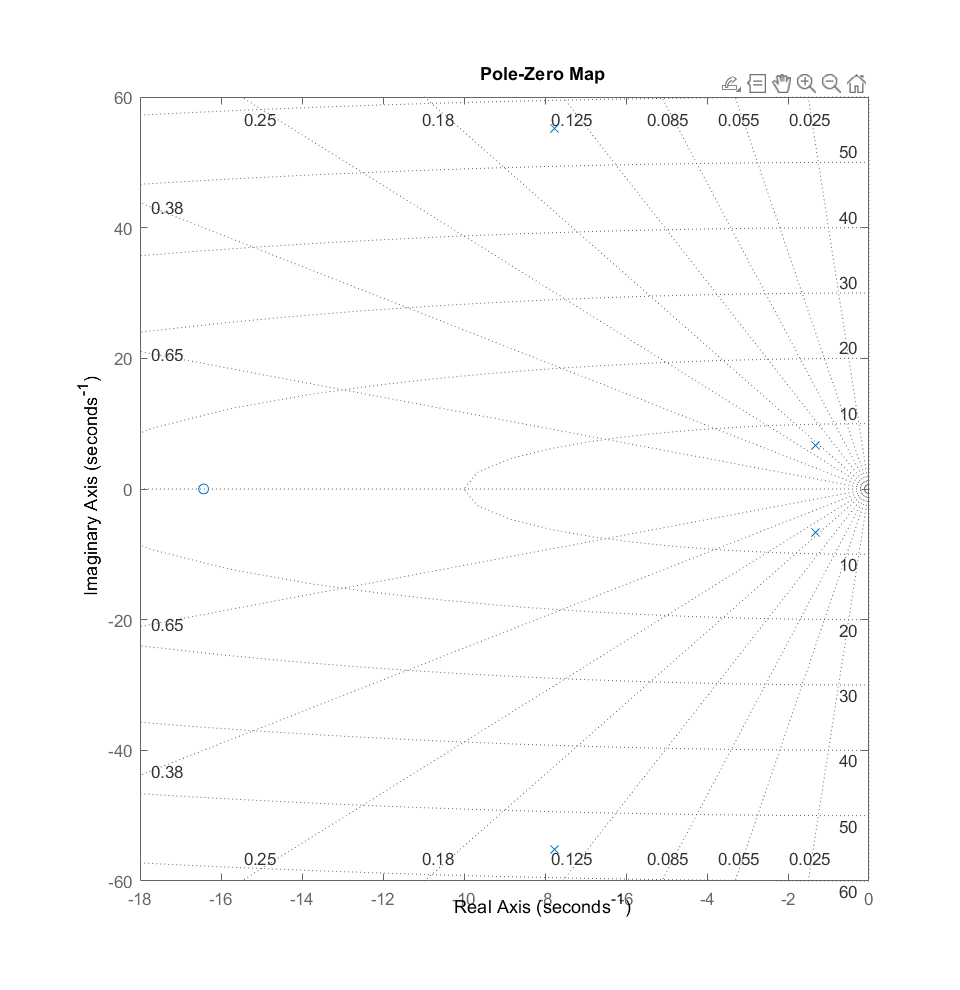

user_prompt_step = 3×1 cell array
    {'0'}
    {'0'}
    {'1'}


step_time = 0

initial_value = 0

final_value = 1

Slope = 0

Start_time = 0

initial_output = 0

delay_time = 0

amplitude = 0

Frequency = 0

prompt={'Enter Sprung Mass (kg): ','Enter Un-Sprung Mass (kg):,','Enter Suspension Spring Constant (N/m):','Enter Damping Coefficient (Ns/m): ','Enter Tire Stiffness (N/m):'};
title_PROMPT='Suspension and Tire Coefficients';
default_Inputs={'320','65','16100','980','188000'};
dims=[1 50];
user_input=inputdlg(prompt,title_PROMPT,dims,default_Inputs); % Dialog box will open up for user input
ms=str2double(user_input(1));
mus=str2double(user_input(2));
ks=str2double(user_input(3));
cs=str2double(user_input(4));
kt=str2double(user_input(5));
Choice=menu('Select The Input','Road Noise Profile','Actuator Force');
if Choice==1
Actuator_Force=0
N=[kt*cs,kt*ks]
D=[ms*mus,(ms+mus)*cs,(ks*ms+kt*ms+ks*mus),cs*kt,ks*kt];
tf_road=tf(N,D)
figure('Position',[0 0 Pix_SS(3)/2 Pix_SS(4) ])
pzmap(tf_road)
grid on
set(gcf,'Visible','on')
Choice_Road_Profile=menu('Choose the Road Profile','Step Input','Ramp Input','Bump Input')
Control=Choice_Road_Profile
if Choice_Road_Profile==1
prompt_road_profile={'Step Time:','Initial Value:','Final Value:'};
title_road_profile='Step Input Parameters:';
default_input_step={'0','0','1'};
dims=[1 50]; 
user_prompt_step=inputdlg(prompt_road_profile,title_road_profile,dims,default_input_step)
step_time=str2double(user_prompt_step(1))
initial_value=str2double(user_prompt_step(2))
final_value=str2double(user_prompt_step(3))
%
Slope=0
Start_time=0
initial_output=0
%
delay_time=0
amplitude=0
Frequency=0
end
if Choice_Road_Profile==2  
prompt_road_profile={'Slope:','Start Time:','Initial Output:'};
title_road_profile='Ramp Input Parameters:';
default_input_ramp={'1','0','0'};
dims=[1 50];    
user_prompt_ramp=inputdlg(prompt_road_profile,title_road_profile,dims,default_input_ramp)
Slope=str2double(user_prompt_ramp(1))
Start_time=str2double(user_prompt_ramp(2))
initial_output=str2double(user_prompt_ramp(3))
delay_time=0
amplitude=0
Frequency=0
%
step_time=0
initial_value=0
final_value=0
end
if Choice_Road_Profile==3
prompt_road_profile={'Delay Time:','Amplitude:','Frequency'};
title_road_profile='Bump Input Parameters:';
default_input_bump={'2','0.2','2'};
dims=[1 50];    
user_prompt_bump=inputdlg(prompt_road_profile,title_road_profile,dims,default_input_bump)
delay_time=str2double(user_prompt_bump(1))
amplitude=str2double(user_prompt_bump(2))
Frequency=str2double(user_prompt_bump(3))
%
Slope=0
Start_time=0
initial_output=0
%
step_time=0
initial_value=0
final_value=0
end
end

if Choice==2
Choice_Road_Profile=4
%
Slope=0
Start_time=0
initial_output=0
%
step_time=0
initial_value=0
final_value=0 
%
delay_time=2
amplitude=0
Frequency=0
N=[mus,0,kt]
D=[ms*mus,(ms+mus)*cs,(ks*ms+kt*ms+ks*mus),cs*kt,ks*kt]
tf_actuator=tf(N,D)
figure('Position',[0 0 Pix_SS(3)/2 Pix_SS(4) ])
pzmap(tf_actuator)
grid on
set(gcf,'Visible','on')
Choice_Actuator_Force=menu('Choose Actuator Force','Constant')
if Choice_Actuator_Force==1
Actuator_Force_Parameters=inputdlg({'Actuator Force (N):'},'Enter the Actuator Force',[1 50],{'200'})
Actuator_Force=str2double(Actuator_Force_Parameters(1))
end
end

%% Data From SImulink
open('Active_suspension_Sim.slx')
y_step=2

y_step = 2

y_slope=2

y_slope = 2

Simout=sim('Active_suspension_Sim.slx')

Simout =   Simulink.SimulationOutput:

     Sprung_Mass_Data_Simulink: [1x1 struct] 
           Sprung_Mass_Data_TF: [1x1 struct] 
                       logsout: [1x1 Simulink.SimulationData.Dataset] 
                          tout: [1001x1 double] 

            SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
                  ErrorMessage: [0x0 char] 


Displacement_tf=Simout.Sprung_Mass_Data_TF.signals(1).values(:,:);
Velocity_tf=Simout.Sprung_Mass_Data_TF.signals(2).values(:,:);
Acceleration_tf=Simout.Sprung_Mass_Data_TF.signals(3).values(:,:);
Time=Simout.Sprung_Mass_Data_TF.time;
Displacement_simulink=Simout.Sprung_Mass_Data_Simulink.signals(1).values(:,:)';
Velocity_simulink=Simout.Sprung_Mass_Data_Simulink.signals(2).values(:,:)';
Acceleration_simulink=Simout.Sprung_Mass_Data_Simulink.signals(3).values(:,:)';
Step_Input=Simout.logsout{3}.Values  

  timeseries

  Common Properties:
            Name: 'Step Input'
            Time: [1001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1001x1 double]
        DataInfo: 

Ramp_Input=Simout.logsout{2}.Values  

  timeseries

  Common Properties:
            Name: 'Ramp Profile'
            Time: [1001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1001x1 double]
        DataInfo: 

Bump_Input=Simout.logsout{4}.Values  

  timeseries

  Common Properties:
            Name: 'Bump Profile'
            Time: [1001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1001x1 double]
        DataInfo: 

Actuator_Input=Simout.logsout{1}.Values  

  timeseries

  Common Properties:
            Name: 'Actuator Force'
            Time: [1x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1 double]
        DataInfo: 

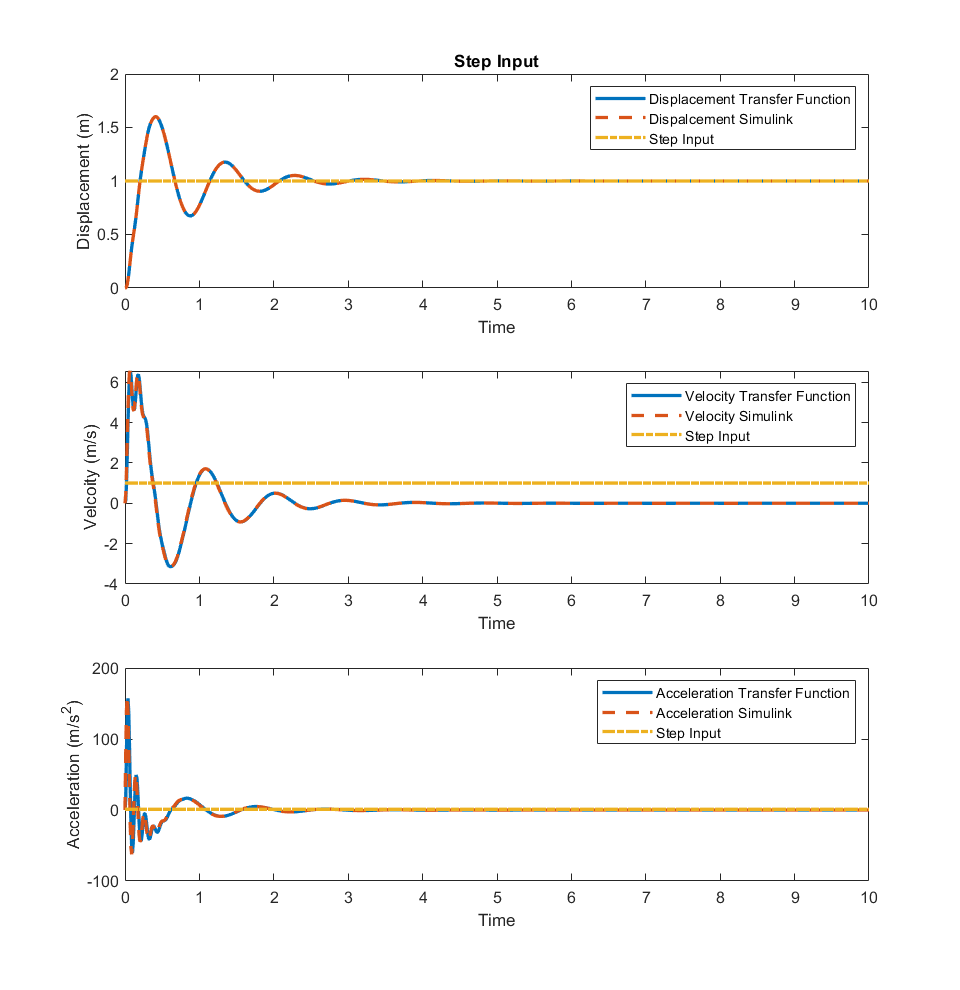

%Road Profiles
if Choice==1
if Choice_Road_Profile==1
figure('Position',[Pix_SS(3)/2 0  Pix_SS(3)/2 Pix_SS(4) ])
subplot(3,1,1)
plot(Time,Displacement_tf,'LineWidth',2)
hold on
plot(Time,Displacement_simulink,'LineWidth',2,"LineStyle",'--')
plot(Step_Input,'LineWidth',2,"LineStyle",'-.'  )
hold off
title('Step Input')
xlabel('Time')
ylabel('Displacement (m)')
legend('Displacement Transfer Function','Dispalcement Simulink','Step Input')
subplot(3,1,2)
plot(Time,Velocity_tf,'LineWidth',2)
hold on
plot(Time,Velocity_simulink,'LineWidth',2,"LineStyle",'--')
plot(Step_Input,'LineWidth',2,"LineStyle",'-.'  )
hold off
xlabel('Time')
ylabel('Velcoity (m/s)')
legend('Velocity Transfer Function','Velocity Simulink','Step Input')
subplot(3,1,3)
plot(Time,Acceleration_tf,'LineWidth',2)
hold on
plot(Time,Acceleration_simulink,'LineWidth',2,"LineStyle",'--')
plot(Step_Input,'LineWidth',2,"LineStyle",'-.'  )
hold off
xlabel('Time')
ylabel('Acceleration (m/s^2)')
legend('Acceleration Transfer Function','Acceleration Simulink','Step Input')
set(gcf,'Visible','on')
end
if Choice_Road_Profile==2
figure('Position',[Pix_SS(3)/2 0  Pix_SS(3)/2 Pix_SS(4) ])
subplot(3,1,1)
plot(Time,Displacement_tf,'LineWidth',2)
hold on
plot(Time,Displacement_simulink,'LineWidth',2,"LineStyle",'--')
plot(Ramp_Input,'LineWidth',2,"LineStyle",'-.'  )
hold off
title('Ramp Input')
xlabel('Time')
ylabel('Displacement (m)')
legend('Displacement Transfer Function','Dispalcement Simulink','Ramp Input')
subplot(3,1,2)
plot(Time,Velocity_tf,'LineWidth',2)
hold on
plot(Time,Velocity_simulink,'LineWidth',2,"LineStyle",'--')
plot(Ramp_Input,'LineWidth',2,"LineStyle",'-.'  )
hold off
xlabel('Time')
ylabel('Velcoity (m/s)')
legend('Velocity Transfer Function','Velocity Simulink','Ramp Input')
axis('auto')
subplot(3,1,3)
plot(Time,Acceleration_tf,'LineWidth',2)
hold on
plot(Time,Acceleration_simulink,'LineWidth',2,"LineStyle",'--')
plot(Ramp_Input,'LineWidth',2,"LineStyle",'-.'  )
hold off
xlabel('Time')
ylabel('Acceleration (m/s^2)')
legend('Acceleration Transfer Function','Accelearation Simulink','Ramp Input')
set(gcf,'Visible','on')
end
if Choice_Road_Profile==3
figure('Position',[Pix_SS(3)/2 0  Pix_SS(3)/2 Pix_SS(4) ])
subplot(3,1,1)
plot(Time,Displacement_tf,'LineWidth',2)
hold on
plot(Time,Displacement_simulink,'LineWidth',2,"LineStyle",'--')
plot(Bump_Input,'LineWidth',2,"LineStyle",'-.'  )
hold off
title('Bump Input')
xlabel('Time')
ylabel('Displacement (m)')
legend('Displacement Transfer Function','Dispalcement Simulink','Bump Input')
subplot(3,1,2)
plot(Time,Velocity_tf,'LineWidth',2)
hold on
plot(Time,Velocity_simulink,'LineWidth',2,"LineStyle",'--')
plot(Bump_Input,'LineWidth',2,"LineStyle",'-.'  )
hold off
xlabel('Time')
ylabel('Velcoity (m/s)')
legend('Velocity Transfer Function','Velocity Simulink','Bump Input')
subplot(3,1,3)
plot(Time,Acceleration_tf,'LineWidth',2)
hold on
plot(Time,Acceleration_simulink,'LineWidth',2,"LineStyle",'--')
plot(Bump_Input,'LineWidth',2,"LineStyle",'-.'  )
hold off
xlabel('Time')
ylabel('Acceleration (m/s^2)')
legend('Acceleration Transfer Function','Acceleration Simulink','Bump Input')
set(gcf,'Visible','on')
end
end

% Actuator Inputs
if Choice==2
  if Choice_Actuator_Force==1
figure('Position',[Pix_SS(3)/2 0  Pix_SS(3)/2 Pix_SS(4) ])
subplot(3,1,1)
hold on
plot(Time,Displacement_tf,'LineWidth',2)
plot(Time,Displacement_simulink,'LineWidth',2,"LineStyle",'--')
title('Constant Actuator Force')
xlabel('Time')
ylabel('Displacement (m)')
legend('Displacement Transfer Function','Displacement Simulink')
axis('auto')
hold off
subplot(3,1,2)
hold on
plot(Time,Velocity_tf,'LineWidth',2)
plot(Time,Velocity_simulink,'LineWidth',2,"LineStyle",'--')
xlabel('Time')
ylabel('Velcoity (m/s)')
legend('Velocity Transfer Function','Velocity Simulink')
axis('auto')
hold off
subplot(3,1,3)
hold on
plot(Time,Acceleration_tf,'LineWidth',2)
plot(Time,Acceleration_simulink,'LineWidth',2,"LineStyle",'--')
xlabel('Time')
ylabel('Acceleration (m/s^2)')
legend('Acceleration Transfer Function','Acceleration Simulink')
set(gcf,'Visible','on')
axis('auto')
hold off
  end
end


